# Distributions of principal component

This live MATLAB script reproduces Fig. 2 from Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms of bovine spermatozoa. R. Soc. Open Sci. 7: 200769.

 

addpath('.\Data','.\Functions','.\Images','.\Movies')
load('Data/pop_pca.mat','modes','coeff','A_mask','B_mask')
num_frames = 100;
total_num = 216;

cell_coeff = zeros(num_frames,total_num,size(modes,2));
for i = 1 : total_num
	cell_coeff(:,i,:) = coeff((i-1)*num_frames+1:i*num_frames,:);
end

lim = 0.72;
min_c1 = -lim*1.1;
max_c1 = lim*1.1;
num_bins = 30;
bins = linspace(min_c1,max_c1,num_bins+1);
mid_bins = (bins(1:end-1) + bins(2:end))/2;
to_plot_A = zeros(num_frames,num_bins);
to_plot_B = zeros(num_frames,num_bins);
for i = 1 : num_frames
	to_plot_A(i,:) = histcounts(cell_coeff(i,A_mask,1),bins,'normalization','pdf');
	to_plot_B(i,:) = histcounts(cell_coeff(i,B_mask,1),bins,'normalization','pdf');
    hist_plot_A(i,:) = histcounts(cell_coeff(i,A_mask,1),bins,'Normalization','probability');
    hist_plot_B(i,:) = histcounts(cell_coeff(i,B_mask,1),bins,'Normalization','probability');
end

% Color scheme
red = [1,0,0];
lightred = [1,1,1]-0.3*[0,1,1];
blue = [0,0,1];
lightblue = [1,1,1]-0.3*[1,1,0];

## Distribution of principal components over time, individuals, and samples

Filters: which sample and which variables do you wish to plot? 

Sample A - fresh sperm

Sample B - thawed sperm

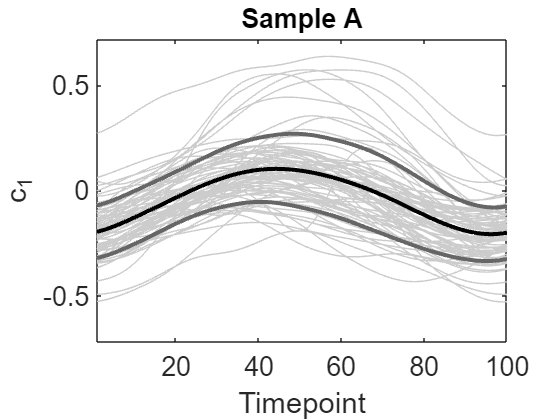

sample ='A'; 
alldataon = true; 
averageon = true; 
upboundon = true; 
loboundon = true;

 

switch true
    case strcmp(sample, 'A')
        mymask = A_mask;
        mytitle = 'Sample A';
    case strcmp(sample, 'B')
        mymask = B_mask;
        mytitle = 'Sample B';
    case strcmp(sample, 'compare')
        alldataon = false;
        mytitle = 'Compare A vs. B';
end

figure
hold on
switch true
    case strcmp(sample, 'compare')
        if alldataon; plot(cell_coeff(:,A_mask,1),'Color',0.8*[1,1,1]); end
        if averageon; plot(mean(cell_coeff(:,A_mask,1),2),'LineWidth',3,'Color',red); end
        if upboundon; plot(mean(cell_coeff(:,A_mask,1),2)+std(cell_coeff(:,A_mask,1),0,2),'LineWidth',3,'Color',lightred); end
        if loboundon; plot(mean(cell_coeff(:,A_mask,1),2)-std(cell_coeff(:,A_mask,1),0,2),'LineWidth',3,'Color',lightred); end
                
        if alldataon; plot(cell_coeff(:,B_mask,1),'Color',0.8*[1,1,1]); end
        if averageon; plot(mean(cell_coeff(:,B_mask,1),2),'LineWidth',3,'Color',blue); end
        if upboundon; plot(mean(cell_coeff(:,B_mask,1),2)+std(cell_coeff(:,B_mask,1),0,2),'LineWidth',3,'Color',lightblue); end
        if loboundon; plot(mean(cell_coeff(:,B_mask,1),2)-std(cell_coeff(:,B_mask,1),0,2),'LineWidth',3,'Color',lightblue); end
    otherwise 
        if alldataon; plot(cell_coeff(:,mymask,1),'Color',0.8*[1,1,1]); end
        if averageon; plot(mean(cell_coeff(:,mymask,1),2),'LineWidth',3,'Color','black'); end
        if upboundon; plot(mean(cell_coeff(:,mymask,1),2)+std(cell_coeff(:,mymask,1),0,2),'LineWidth',3,'Color',0.4*[1,1,1]); end
        if loboundon; plot(mean(cell_coeff(:,mymask,1),2)-std(cell_coeff(:,mymask,1),0,2),'LineWidth',3,'Color',0.4*[1,1,1]); end
end
set(gca,'FontSize',20)
xlim([1,100])
ylim(lim*[-1,1])
xlabel('Timepoint')
ylabel('c_1')
box on
title(mytitle,'FontSize',20)

## Histograms of principal components over time, individuals, and samples

Filters: which sample and which variables do you wish to plot?

Sample A - fresh sperm

Sample B - thawed sperm

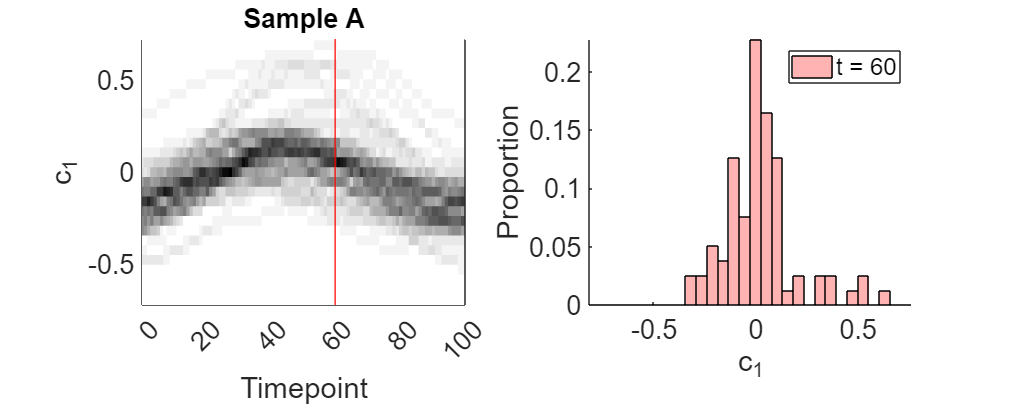

sample ='A'; 

switch true
    case strcmp(sample, 'A')
        to_plot = to_plot_A;
        hist_plot = hist_plot_A;
        mytitle = 'Sample A';
    case strcmp(sample, 'B')
        to_plot = to_plot_B;
        hist_plot = hist_plot_B;
        mytitle = 'Sample B';
end

timepoint1 = 60;
timepoint2 = 25; t2on = false; 

 

fig = figure;
fig.Position(3:4) = [1250 500];
subplot(1,2,1)
hold on
h = pcolor((1:num_frames) -0.5 ,mid_bins,to_plot');
set(h, 'EdgeColor', 'none');
xlim([1,100])
ylim(lim*[-1,1]); yl = ylim;
plot(timepoint1*[1,1],yl,'-','Color',red,'LineWidth',1)
if t2on; plot(timepoint2*[1,1],yl,'-','Color',blue,'LineWidth',1); end
xlabel('Timepoint')
ylabel('c_1')
box on
set(gca,'FontSize',20,'XTick',[1,20,40,60,80,100],'XTickLabel',{'0','20','40','60','80','100'})
colormap('gray')
colormap(flipud(colormap))
title(mytitle,'FontSize',20)

subplot(1,2,2)
hold on; 
mybarwidth = 1;
if t2on
    b = bar(bins(1:end-1),[hist_plot(timepoint1,:); hist_plot(timepoint2,:)]','BarWidth',mybarwidth);
    b(1).FaceColor = lightred;
    b(2).FaceColor = lightblue;
    legend([b(2),b(1)],{['t = ' num2str(timepoint1)],['t = ' num2str(timepoint2)]})
else
    b = bar(bins(1:end-1),hist_plot(timepoint1,:)','BarWidth',mybarwidth);
    b.FaceColor = lightred;
    legend(b(1),{['t = ' num2str(timepoint1)]})
end
xlabel('c_1')
ylabel('Proportion')
set(gca,'FontSize',20)
axis tight